A = [1 1 1 1 1; 1 1 1 0 0; 0 0 0 1 1 ;0 1 0 1 0; 1 0 1 0 1; 1 0 0 0 0; 0 1 0 0 0 ; 0 0 1 0 0; 0 0 0 1 0; 0 0 0 0 1;]'

gfrank(A)

B = [1 1 1 0 0 0; 0 0 0  1 1 1; 0 1 0 1 0 1; 1 0 1 0 1 0; 0 0 1 1 0 0; 1 1 0 0 1 1; 1  0 0 0 0 0; 0 1 0 0 0 0; 0 0 1 0 0 0; 0 0 0 1 0 0 ; 0 0 0 0 1 0; 0 0 0 0 0 1;]'

gfrank(B)

C = [1 1 1 1 1 1 1; 1 1 1 1 0 0 0; 0 0 0 1 1 1 1; 1 0 1 1 0 0 1; 0 1 0 0 1 0 1;1 1 0 0 1 1 1; 0 0 1 1 1 1 0;1 0 0 0 0 0 0; 0 1 0 0 0 0 0; 0 0 1 0 0 0 0; 0 0 0 1 0 0 0; 0 0 0 0 1 0 0; 0 0 0 0 0 1 0; 0 0 0 0 0 0 1;]'

gfrank(C)

matrixstruct(9).name = 'Lin105'

matrixstruct(9).matrix = A

matrixstruct(10).name = 'Lin126'

matrixstruct(10).matrix = B

matrixstruct(11).name = 'Lin146'

matrixstruct(11).matrix = C

C>B>ExHam84>Aの順番に符号的限界や上界に近いグラフになった。C,B,ExHam84をみると符号長を増やすとセキュリティーレートも向上するように見えるがLin105がExHam84を下回っているのを見ると案外関係ないのかもしれない

D = [1 1 1 1; 1 1 1 0; 0 1 1 0; 1 0 0 1; 1 0 0 0; 0 1 0 0;0 0 1 0; 0 0 0 1]'

matrixstruct(12).name = 'Lin84'

matrixstruct(12).matrix = D

Lin = [0.9889 0.9868 0.9870 0.9871 0.9882 0.9881 0.9897]'

Lin =     0.9889
    0.9868
    0.9870
    0.9871
    0.9882
    0.9881
    0.9897


ExLin = [0.9923 0.9809 0.9837 0.9878 0.9863 0.9888 0.9899]'

ExLin =     0.9923
    0.9809
    0.9837
    0.9878
    0.9863
    0.9888
    0.9899


n = [1 2 3 4 5 6 7]';
T = array2table(n)

T = 7×1 table
    n
    _

    1
    2
    3
    4
    5
    6
    7


T{:,'Lin'} = Lin

T = 7×2 table
    n     Lin  
    _    ______

    1    0.9889
    2    0.9868
    3     0.987
    4    0.9871
    5    0.9882
    6    0.9881
    7    0.9897


T{:,'ExLin'} = ExLin

T = 7×3 table
    n     Lin      ExLin 
    _    ______    ______

    1    0.9889    0.9923
    2    0.9868    0.9809
    3     0.987    0.9837
    4    0.9871    0.9878
    5    0.9882    0.9863
    6    0.9881    0.9888
    7    0.9897    0.9899


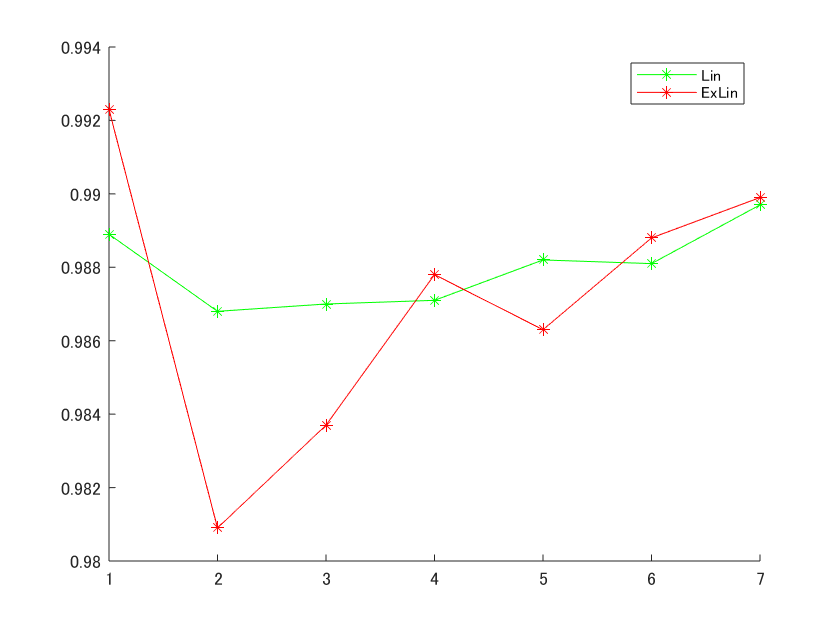

hold on 
plot(T{:,1},T{:,2} ,'g*-')
plot(T{:,1},T{:,3} ,'r*-')
legend('Lin','ExLin')
hold off